# `istidal` documentation

The `istidal` function returns logical true for everything seaward of the landward limit of flexure (including open ocean and ice shelves) detected by InSAR according to MEaSURES Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. This is the same thing as the logical NOT of `isgrounded`. 

The Antarctic Boundaries dataset is described on the NSIDC site [here](http://nsidc.org/data/NSIDC-0709). An overview of the tools in this AMT plugin can be found [here](Antbounds_Contents.html).

## Syntax

## Description

`tf = istidal(lati,loni)` returns true for all geo locations `(lati,loni)` not identified as grounded ice in the Mask_Antactica_v2.tif (sic) dataset. 

`tf = istidal(xi,yi)` returns true for all locations not identified as grounded ice in Mask_Antactica_v2.tif (sic), where input coordinates are automatically determined to be polar stereographic (true lat 71 S) meters if their values exceed the normal lat,lon range. 

## Example: Mask a gravity dataset:

This example uses a [Gravity Plugin for AMT](https://www.mathworks.com/matlabcentral/fileexchange/54915-antarctic-gravity-data) to load some example data, but I'll show you how you can follow along without loading that dataset. Whether you have the gravity plugin or not, begin by creating a 300 km wide grid centered on PIG, at 0.25 km resolution:

[lat,lon] = psgrid('pine island glacier',300,0.25);

If you have the gravity plugin, interpolate gravity values to the grid like this: 

FA = gravity_interp(lat,lon,'free air');

If you don't have the gravity plugin you can simply use random data like this: 

Use `istidal` to find out which parts of the dataset are not over grounded ice: 

salty = istidal(lat,lon);

Mask-out all tidal ice (use the tilde for NOT) by setting it to NaN: 

FA(~salty) = NaN;

Note, the `istidal` function returns the logical NOT of the `isgrounded` function, so we alternatively could have done the above step like this: 

FA(isgrounded(lat,lon)) = NaN;

Plot the gravity data corresponding to wherever there's ocean water: 

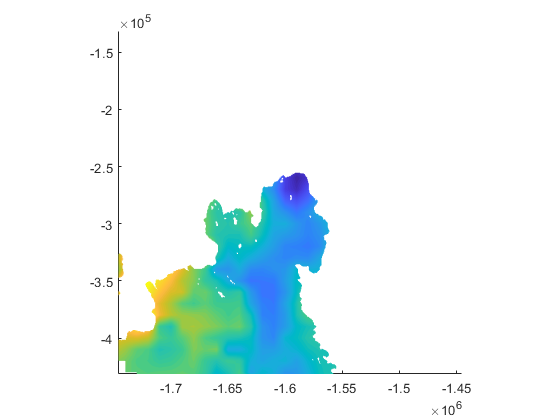

pcolorps(lat,lon,FA)
axis tight

For context, overlay a red grounding line and a black coastline: 

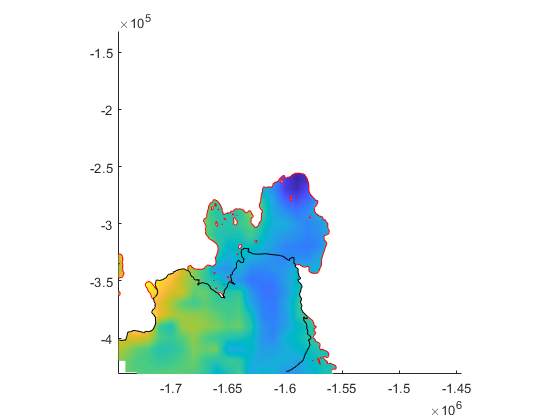

antbounds('gl','r') 
antbounds('coast','k')

## Citing this dataset

If you use this dataset, please cite the following: 

- **The dataset:** Mouginot, J., B. Scheuchl, and E. Rignot. 2017. MEaSUREs Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. [Indicate subset used]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. [http://dx.doi.org/10.5067/AXE4121732AD](http://dx.doi.org/10.5067/AXE4121732AD). 

- **Literature citation:** Rignot, E., S. S. Jacobs, J. Mouginot, and B. Scheuchl. 2013. Ice-shelf melting around Antarctica, Science. 341. 266-270. [http://dx.doi.org/10.1126/science.1235798](http://dx.doi.org/10.1126/science.1235798). 

- **Antarctic Mapping Tools:** Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function and supporting documentation were written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), November 2016. Updated May 2017. 